## Matlab code for generateing main figure 3 in the following paper:

[Single cell transcriptomics of human epidermis identifies basal stem cell transition states](https://www.nature.com/articles/s41467-020-18075-7), S. Wang, M. Drummond, C.Guerrero-Juarez, E.Tarapore, A.MacLean, A. Stabell, S. Wu, G. Gutierrez, B. That, C. Benavente, Q. Nie & S. X. Atwood, Nature Communications, 2020.

- All the results are generated by applying SoptSC to the single-cell rna-seq data, for detailed useage of SoptSC, please refer to

- [https://github.com/WangShuxiong/SoptSC](https://github.com/WangShuxiong/SoptSC)

- Some figures are generated using custermized code below

% Add tools into matlab path
addpath('Data');
addpath('NNDSVD');
addpath('symnmf2');
addpath('EE');
addpath('vinlinplot');
addpath('scTools');
addpath('scTools/graphViz2Mat1');
addpath('Cell_Cell_Communication');
addpath('gephi');
addpath('Results');

#### Step 1 (Required)

Load data

%% Step 1: load data
load Data_Figure3.mat;

% set folder to save all figures
folder = 'Results\Fig3';
folder1 = 'Results/Fig3';

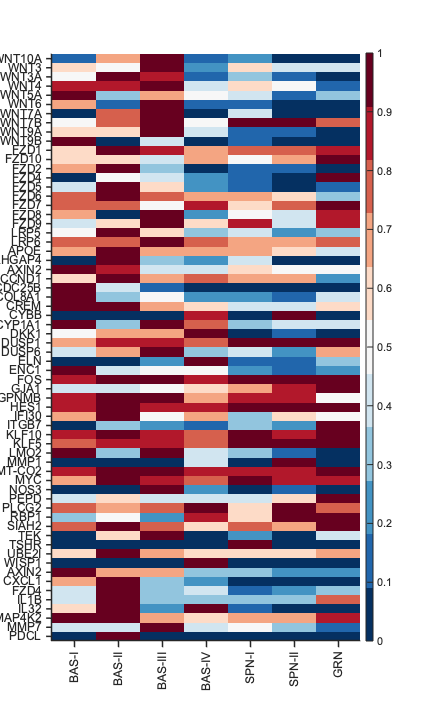

%% plot average expression of selected genes in each cluster
figname = 'LR_mean';

gene_selected = [unique(Data_Figure3.Lig);unique(Data_Figure3.Rec);unique(Data_Figure3.target_up);unique(Data_Figure3.target_down)];
reorder = 1:Data_Figure3.No_cluster;
plot_mean_matrix(Data_Figure3.data,gene_selected,Data_Figure3.allgenes,Data_Figure3.cluster_legend,Data_Figure3.cluster_label,...
    reorder,figname,folder);

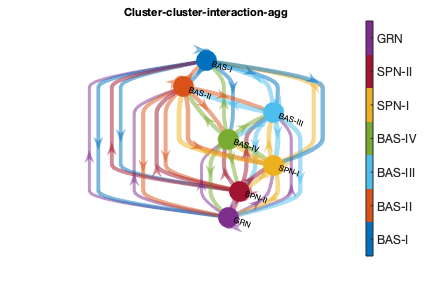

%% plot aggegration of cluster-cluster interations (aggegration of all l-r pair)
figname = 'Cluster-cluster-interaction-agg';

threshold = 0.3;
plot_sig_network(Data_Figure3.P_cluster_agg,Data_Figure3.cluster_label,threshold,Data_Figure3.cluster_legend,folder,figname,...
    Data_Figure3.cluster_color);

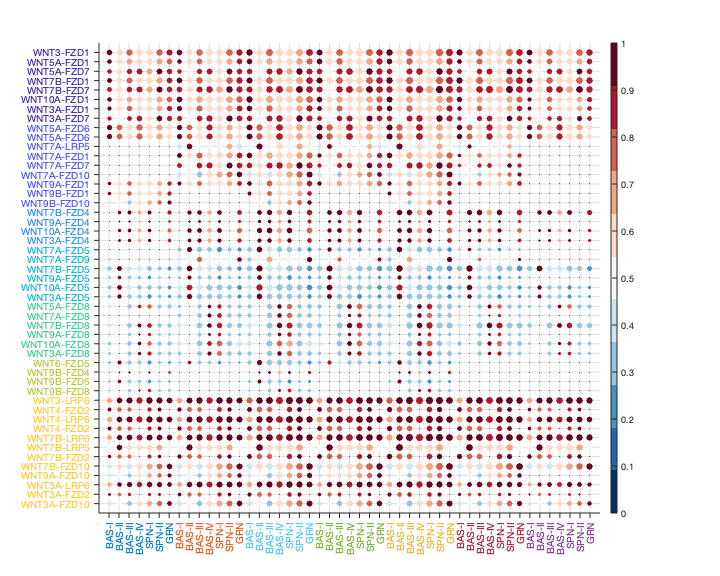

%% plot dot-heatmap at cluster-level for all lig-rec pairs
figname = 'Dot_heatmap';
NC_LR = length(unique(Data_Figure3.cluster_label_lr));
cluster_order_lr = 1:NC_LR;
reorder = 1:Data_Figure3.No_cluster;
plot_dot_heatmap(Data_Figure3.P_cluster_each_lr,Data_Figure3.P_dot_size,Data_Figure3.Lig,Data_Figure3.Rec,...

    Data_Figure3.cluster_legend,Data_Figure3.cluster_color,Data_Figure3.color_lr,reorder,Data_Figure3.cluster_label_lr,...
    cluster_order_lr,folder,figname);

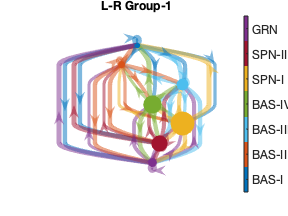

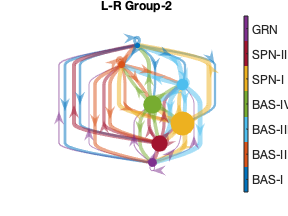

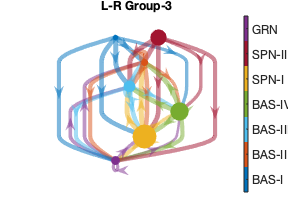

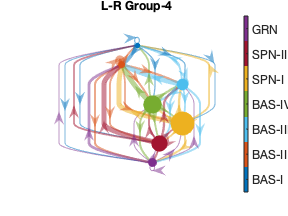

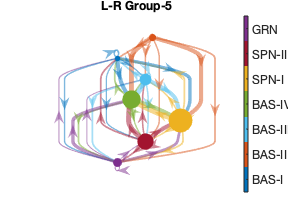

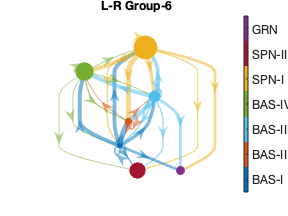

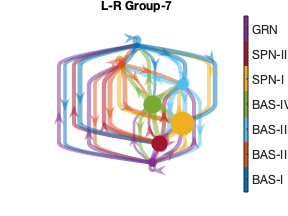

%% plot cluster-cluster interactions based on the groups of ligand-receptor pairs
threshold = 0.1;
figname = 'Signaling_cluster';
cluster_order_lr = 1:NC_LR;
plot_sig_network_group_lr(Data_Figure3.P_cluster_each_lr,Data_Figure3.cluster_legend,threshold,Data_Figure3.cluster_label,...

    Data_Figure3.cluster_label_lr,cluster_order_lr,Data_Figure3.cluster_color,figname,folder);

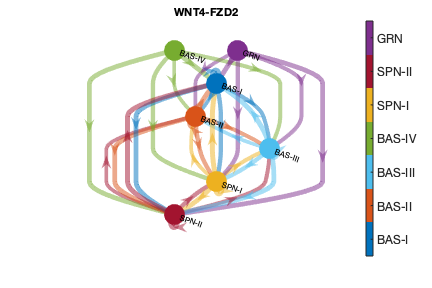

%% plot cluster-cluster interations for a specific ligand-receptor pair
lr_number = 3; % plot the 3rd l-r pair
figname = [Data_Figure3.Lig{lr_number} '-' Data_Figure3.Rec{lr_number}];
threshold = 0.3;
plot_sig_network(Data_Figure3.P_cluster_each_lr{lr_number},Data_Figure3.cluster_label,threshold,Data_Figure3.cluster_legend,...
    folder,figname,Data_Figure3.cluster_color);